# 상관관계분석

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
BAT1 =B0005;
BAT2 =B0006;
BAT3 =B0007; 
BAT4 =B0018; 


## 피쳐 얻어오기

[cap,maxTemp,maxTimeDelta,abnormal,ohm,re_c,re_d] = extract_feature(BAT1);
%maxTimeDelta(abnormal) <= 이상값을 변경하는 것도 필요하다. 차후에.
dataVectorAll = [cap'  maxTimeDelta' maxTemp' ohm'  re_c' re_d'];
dataVector = [cap'  maxTimeDelta'];

[cap2,maxTemp2,maxTimeDelta2,abnormal2,ohm2,re_c2,re_d2] = extract_feature(BAT2);
dataVectorAll2 = [cap2'  maxTimeDelta2' maxTemp2' ohm2'  re_c2' re_d2'];
dataVector2 = [cap2'  maxTimeDelta2'];

[cap3,maxTemp3,maxTimeDelta3,abnormal3,ohm3,re_c3,re_d3] = extract_feature(BAT3);
dataVectorAll3 = [cap3'  maxTimeDelta3' maxTemp3' ohm3'  re_c3' re_d3'];
dataVector3 = [cap3'  maxTimeDelta3'];

%{
% extract_feature function has errors on BAT4
[cap4,maxTemp4,maxTimeDelta4,abnormal4,ohm4,re_c4,re_d4] = extract_feature(BAT4);
dataVectorAll4 = [cap4'  maxTimeDelta4' maxTemp4' ohm4'  re_c4' re_d4'];
dataVector4 = [cap4'  maxTimeDelta4'];
%}

## **상관관계 확인하기**

# corrplot

Plot variable correlations

`'type'` **—** **Correlation coefficient**

`'Pearson'` (default) | `'Kendall'` | `'Spearman'`

`R` **— Correlations **Correlations between pairs of variables in [`X`](https://www.mathworks.com/help/releases/R2021a/econ/corrplot.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AU%20AS%20CM%20VP%20CT%20CF%20NN%20DS%20ET%20EC%20FI%20FL%20GD%20IA%20IP%20IC%20LS%20MG%20ME%20CO%20MR%20AM%20MT%20OP%20RL%20RB%20RF%20RO%20RC%20RR%20TF%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20SF%20ST%20SM%20TA%20WL&docviewer=helpbrowser&docrelease=R2021a&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DCC5GCV&searchsource=mw&snc=MMECFQ&container=jshelpbrowser#btbc5t7-X) that are displayed in the plots, returned as a `numVars`-by-`numVars` matrix.

`PValue` **—** ***p*****-values ***p*-values corresponding to significance tests on the elements of `R`, returned as a `numVars`-by-`numVars` matrix. The p-values are used to test the hypothesis of no correlation against the alternative of nonzero correlation.

#### `Pearson` ( 디폴트) - 모든 배터리 / 모든 변수

maxTimeDelta 를 보면 히스토그램 분포를 보면 2개가 이상한 값이 있다. 이것이 영향을 미친다.

3가지 저항 모두는 높은 음의 상관관계를 갖는다. 그러나 EIS 로 측정된 Re,Rct 는 online 환경에서 적용하기 어려우므로 제외한다.

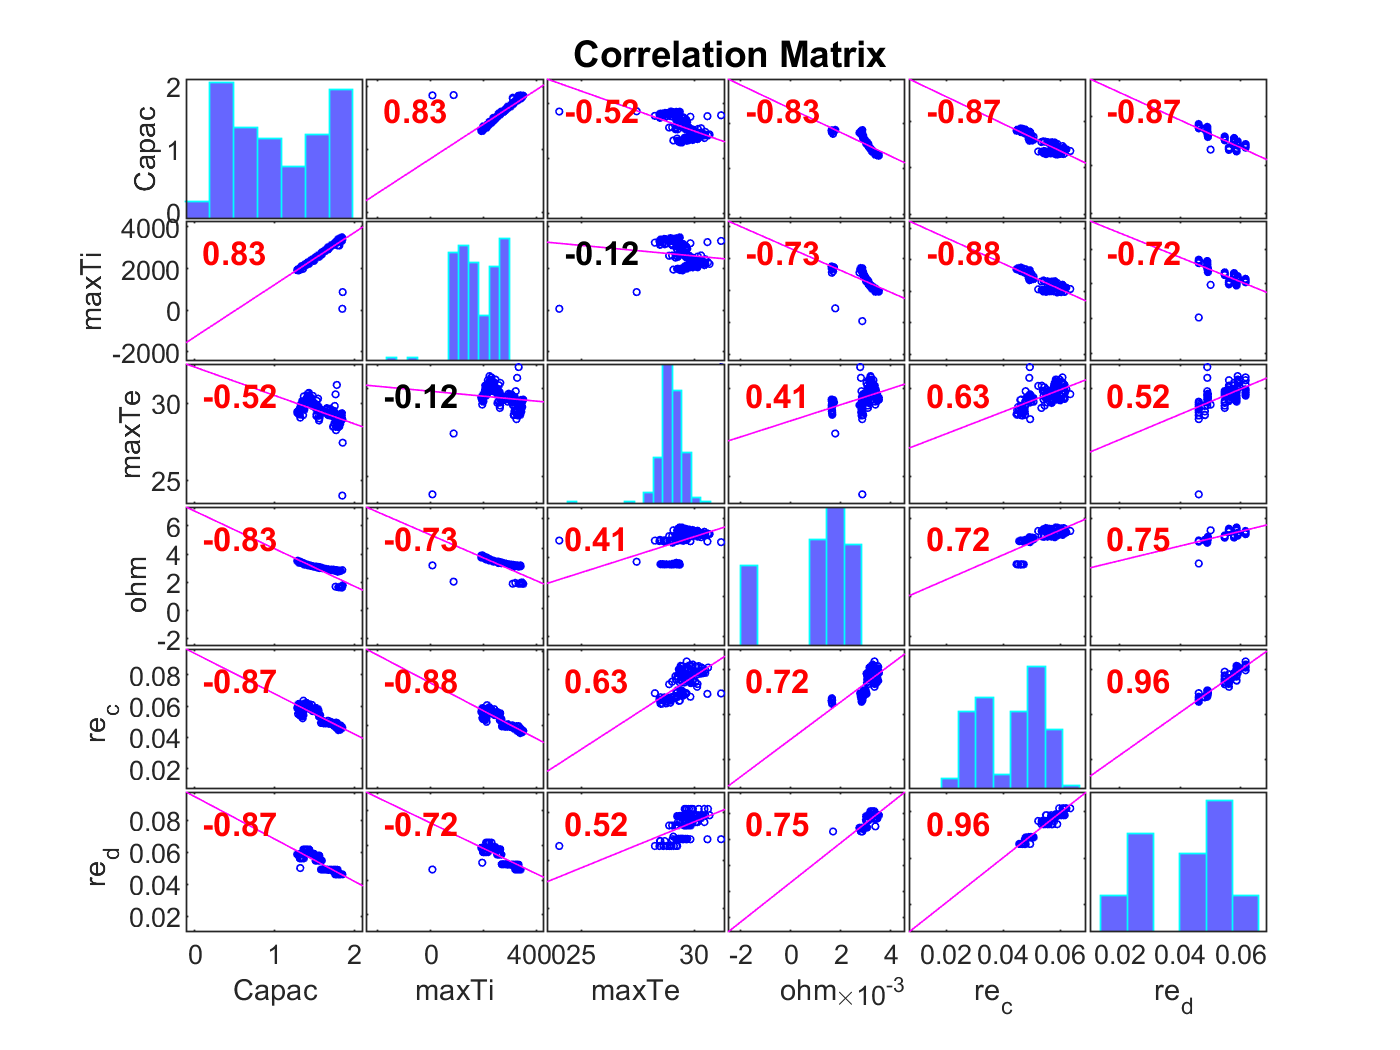

R =    1.000000000000000   0.827358771389820  -0.516900001535531  -0.833443684479026  -0.870743474988187  -0.866633960568570
   0.827358771389820   1.000000000000000  -0.118949357686428  -0.725106714171832  -0.877213025345867  -0.717508320779686
  -0.516900001535531  -0.118949357686428   1.000000000000000   0.406314174514403   0.633725879222206   0.523203708345465
  -0.833443684479026  -0.725106714171832   0.406314174514403   1.000000000000000   0.723468589440991   0.753461379602933
  -0.870743474988187  -0.877213025345867   0.633725879222206   0.723468589440991   1.000000000000000   0.963016262140253
  -0.866633960568570  -0.717508320779686   0.523203708345465   0.753461379602933   0.963016262140253   1.000000000000000


PValue =    1.000000000000000   0.000000000000000   0.000000000000626   0.000000000000000   0.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000   0.123477742920479   0.000000000000000   0.000000000000000   0.000000000000000
   0.000000000000626   0.123477742920479   1.000000000000000   0.000000042245105   0.000000000000001   0.000000000063664
   0.000000000000000   0.000000000000000   0.000000042245105   1.000000000000000   0.000000000000000   0.000000000000000
   0.000000000000000   0.000000000000000   0.000000000000001   0.000000000000000   1.000000000000000   0.000000000000000
   0.000000000000000   0.000000000000000   0.000000000063664   0.000000000000000   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVectorAll,'type','Pearson','testR','on','varNames',{'Capacity','maxTimeDelta','maxTemp','ohm','re_c','re_d'})

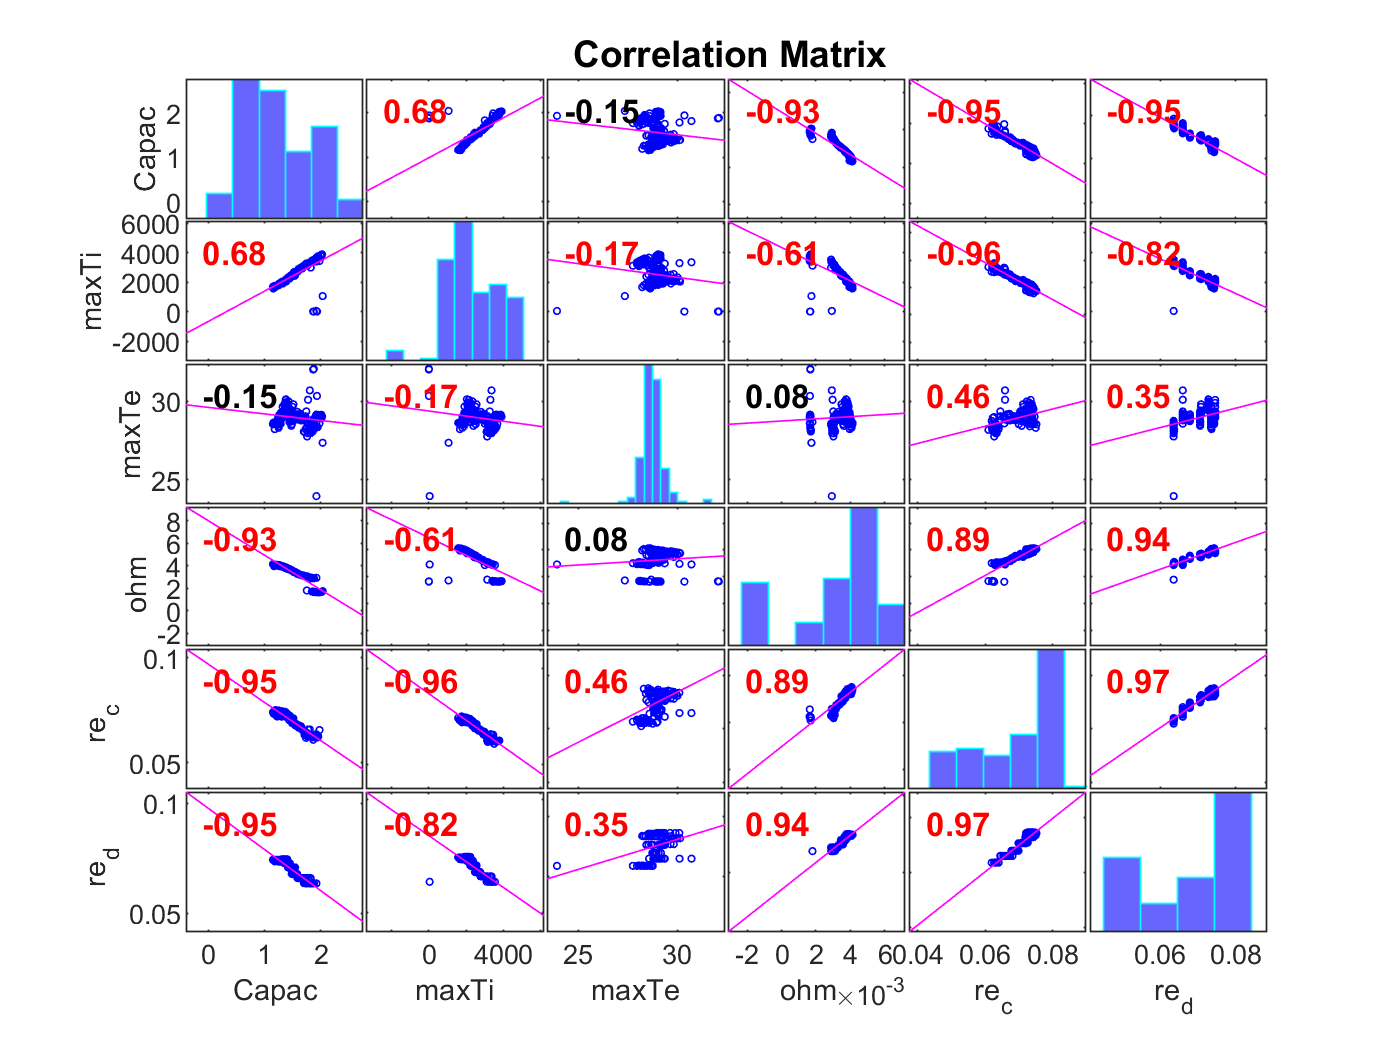

R =    1.000000000000000   0.681618156195910  -0.146635944006116  -0.934590103288131  -0.954765634006651  -0.946372097610276
   0.681618156195910   1.000000000000000  -0.174905859780304  -0.612626587675604  -0.964810816933720  -0.822225684380052
  -0.146635944006116  -0.174905859780304   1.000000000000000   0.079455750348269   0.456093986481949   0.353923553632928
  -0.934590103288131  -0.612626587675604   0.079455750348269   1.000000000000000   0.889166677322465   0.937505639208407
  -0.954765634006651  -0.964810816933720   0.456093986481949   0.889166677322465   1.000000000000000   0.968392699702029
  -0.946372097610276  -0.822225684380052   0.353923553632928   0.937505639208407   0.968392699702029   1.000000000000000


PValue =    1.000000000000000   0.000000000000000   0.057116802739304   0.000000000000000   0.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000   0.022938197116769   0.000000000000000   0.000000000000000   0.000000000000000
   0.057116802739304   0.022938197116769   1.000000000000000   0.304475482224972   0.000000049450418   0.000023685940573
   0.000000000000000   0.000000000000000   0.304475482224972   1.000000000000000   0.000000000000000   0.000000000000000
   0.000000000000000   0.000000000000000   0.000000049450418   0.000000000000000   1.000000000000000   0.000000000000000
   0.000000000000000   0.000000000000000   0.000023685940573   0.000000000000000   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVectorAll2,'type','Pearson','testR','on','varNames',{'Capacity','maxTimeDelta','maxTemp','ohm','re_c','re_d'})

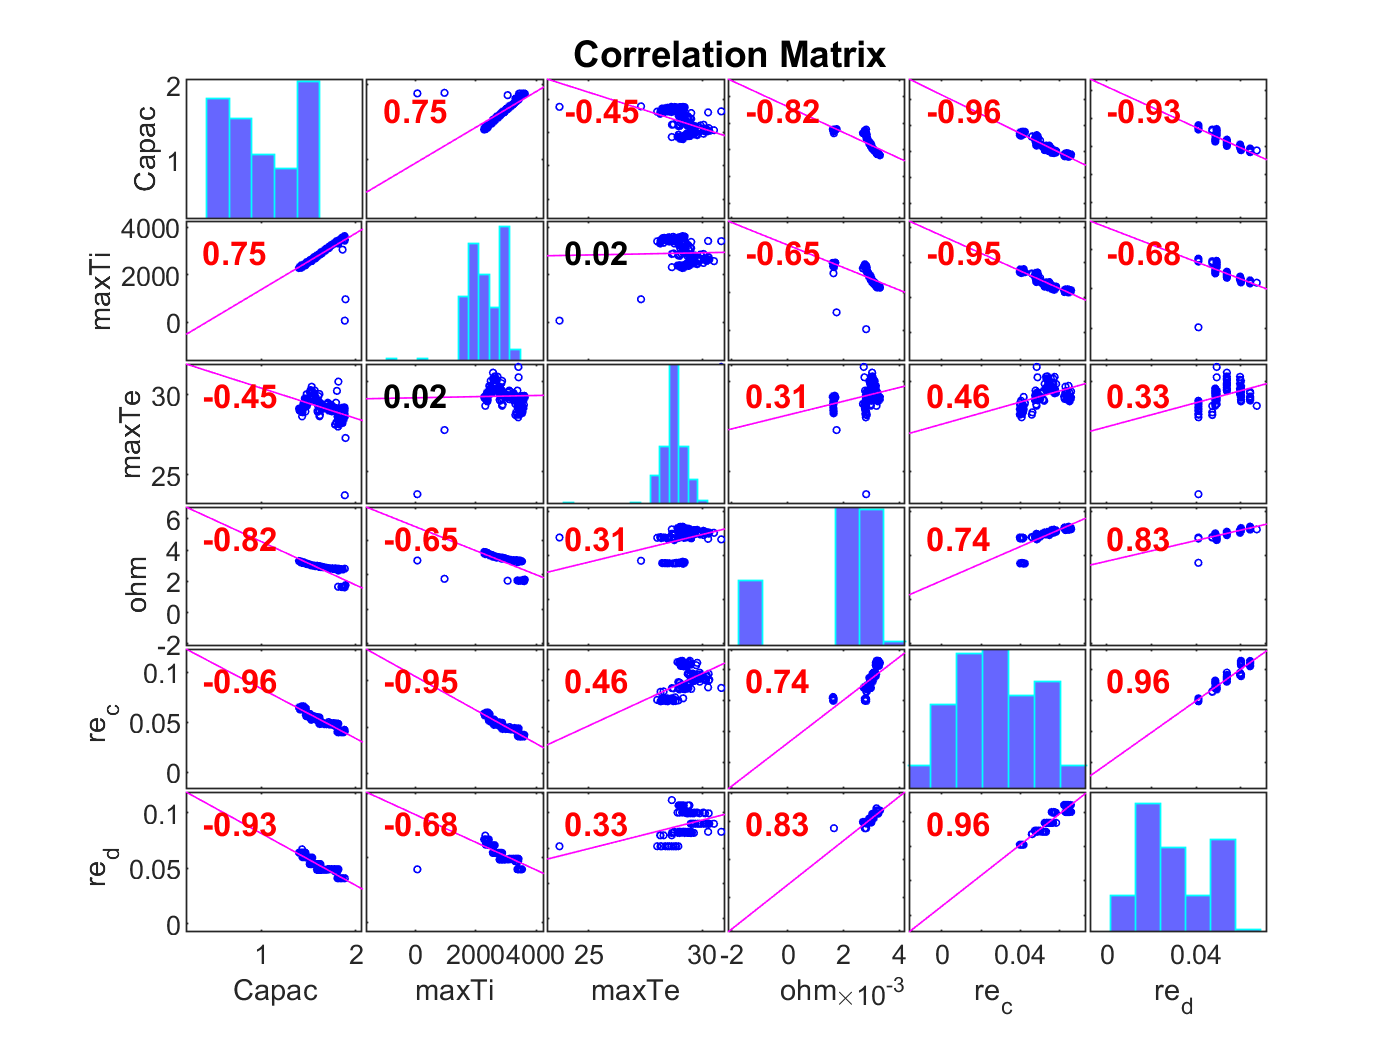

R =    1.000000000000000   0.753778988847614  -0.453365392906081  -0.821605213651199  -0.957212354148267  -0.926275553257116
   0.753778988847614   1.000000000000000   0.024441454018508  -0.646725206427403  -0.954046628941219  -0.681666894588669
  -0.453365392906081   0.024441454018508   1.000000000000000   0.311998885715477   0.456922072253624   0.330397726419136
  -0.821605213651199  -0.646725206427403   0.311998885715477   1.000000000000000   0.735785847723661   0.827670838944615
  -0.957212354148267  -0.954046628941219   0.456922072253624   0.735785847723661   1.000000000000000   0.956276887777456
  -0.926275553257116  -0.681666894588669   0.330397726419136   0.827670838944615   0.956276887777456   1.000000000000000


PValue =    1.000000000000000   0.000000000000000   0.000000000602648   0.000000000000000   0.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000   0.752436818778609   0.000000000000000   0.000000000000000   0.000000000000000
   0.000000000602648   0.752436818778609   1.000000000000000   0.000036364782015   0.000000046439398   0.000085510158679
   0.000000000000000   0.000000000000000   0.000036364782015   1.000000000000000   0.000000000000000   0.000000000000000
   0.000000000000000   0.000000000000000   0.000000046439398   0.000000000000000   1.000000000000000   0.000000000000000
   0.000000000000000   0.000000000000000   0.000085510158679   0.000000000000000   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVectorAll3,'type','Pearson','testR','on','varNames',{'Capacity','maxTimeDelta','maxTemp','ohm','re_c','re_d'})

%[R,PValue] = corrplot(dataVectorAll4,'type','Pearson','testR','on','varNames',{'Capacity','maxTimeDelta','maxTemp','ohm','re_c','re_d'})

#### `Pearson` ( 디폴트) -   관심변수 - 충전시 최대온도까지의 시간

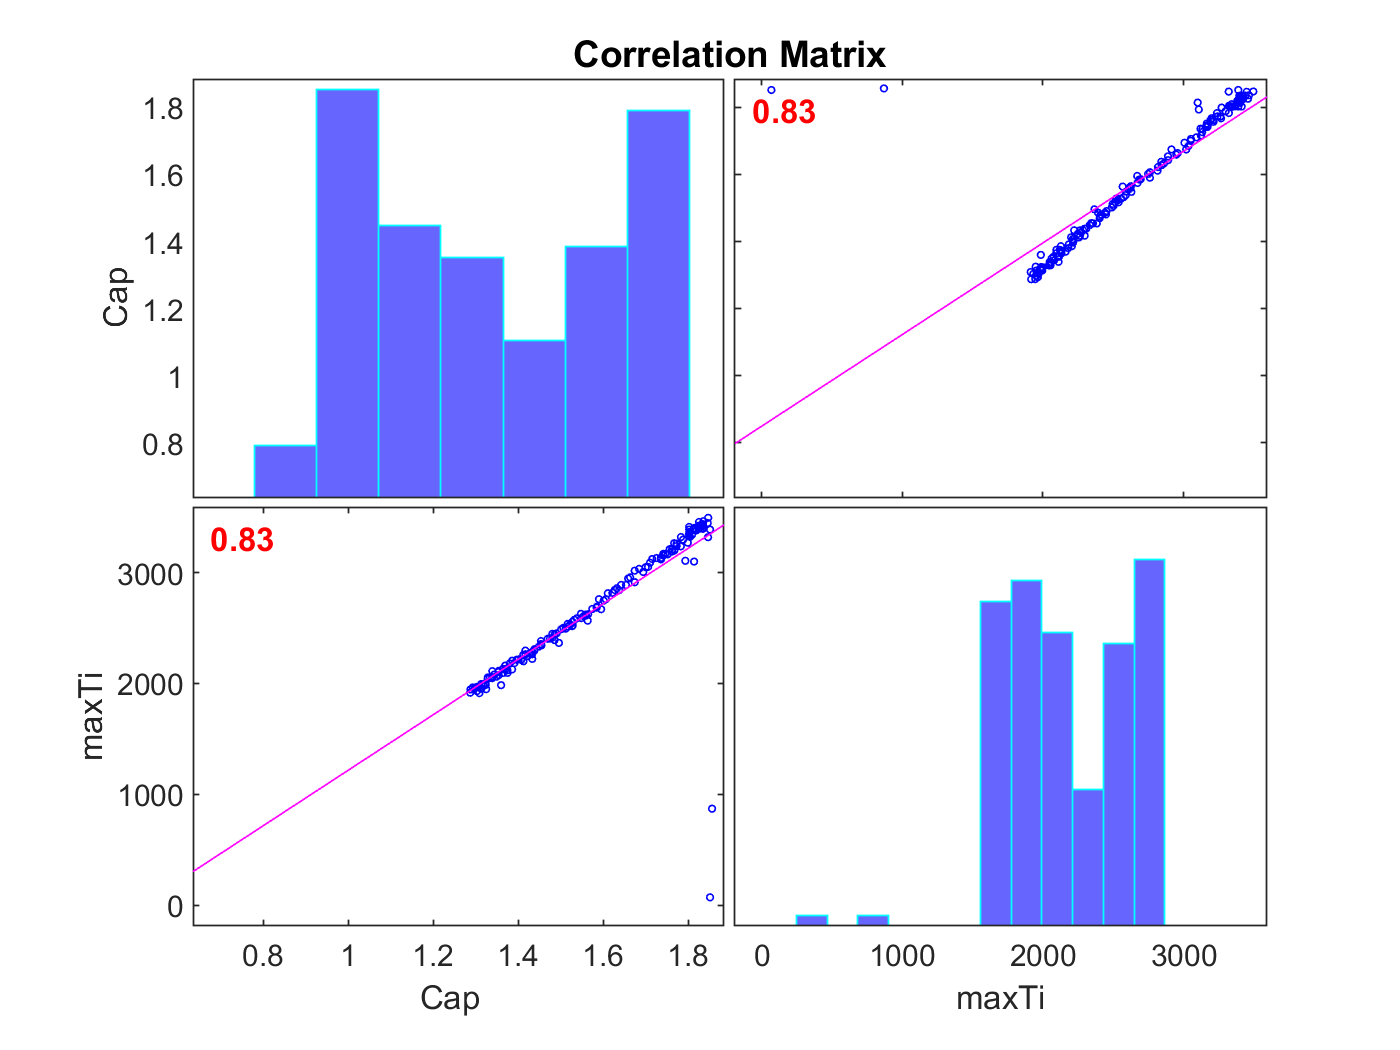

R =    1.000000000000000   0.827358771389819
   0.827358771389819   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector,'type','Pearson','testR','on','varNames',{'Cap','maxTimeDelta'})

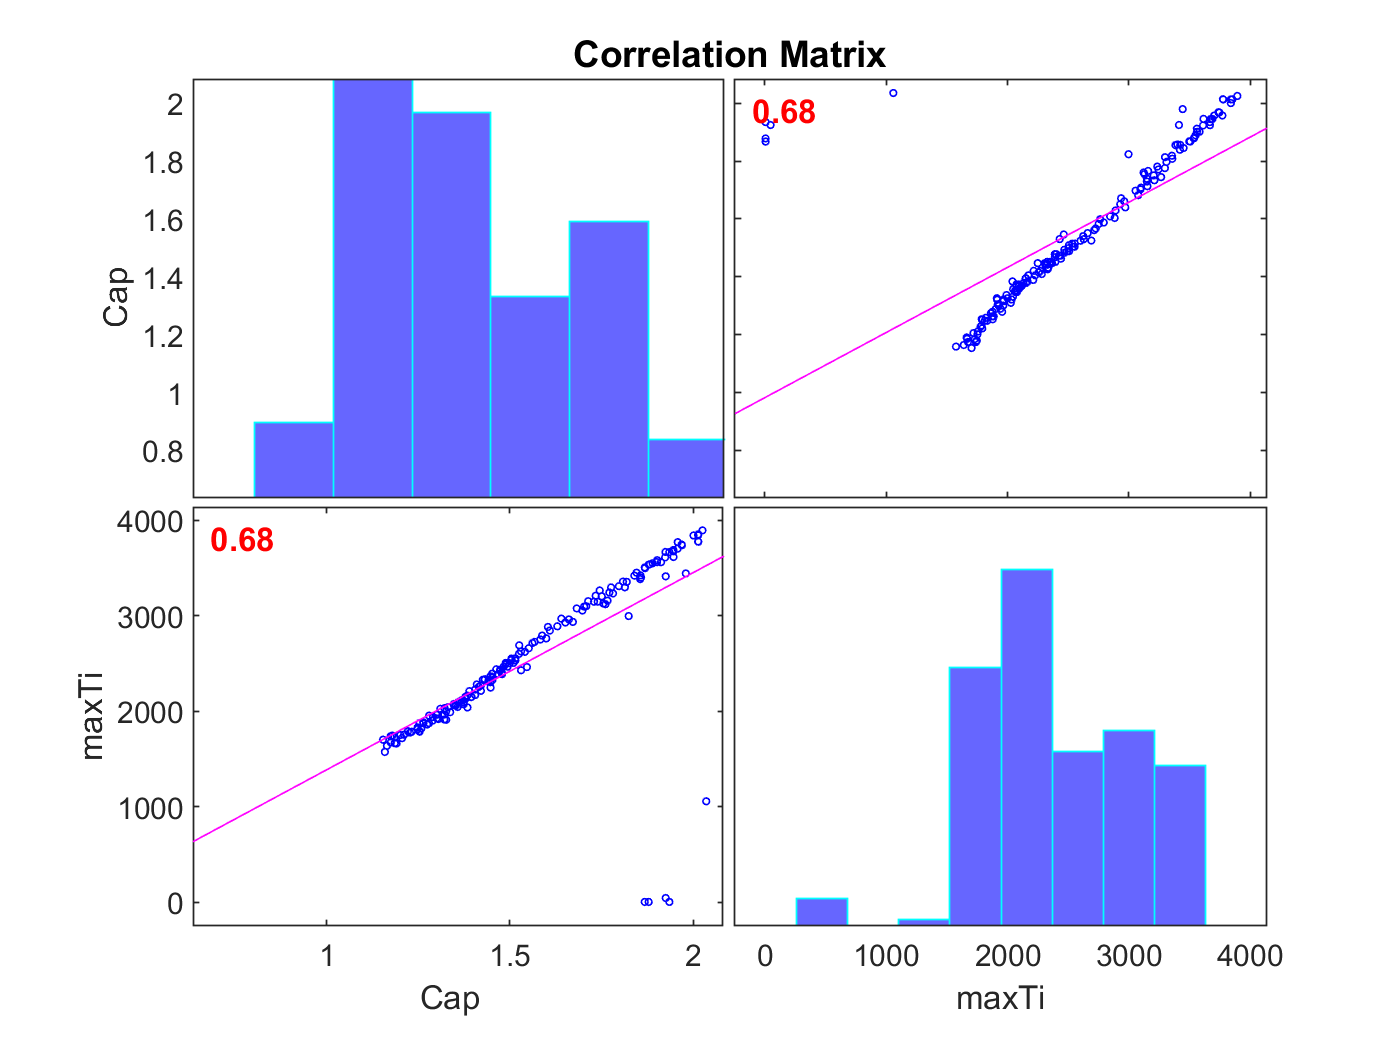

R =    1.000000000000000   0.681618156195909
   0.681618156195909   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector2,'type','Pearson','testR','on','varNames',{'Cap','maxTimeDelta'})

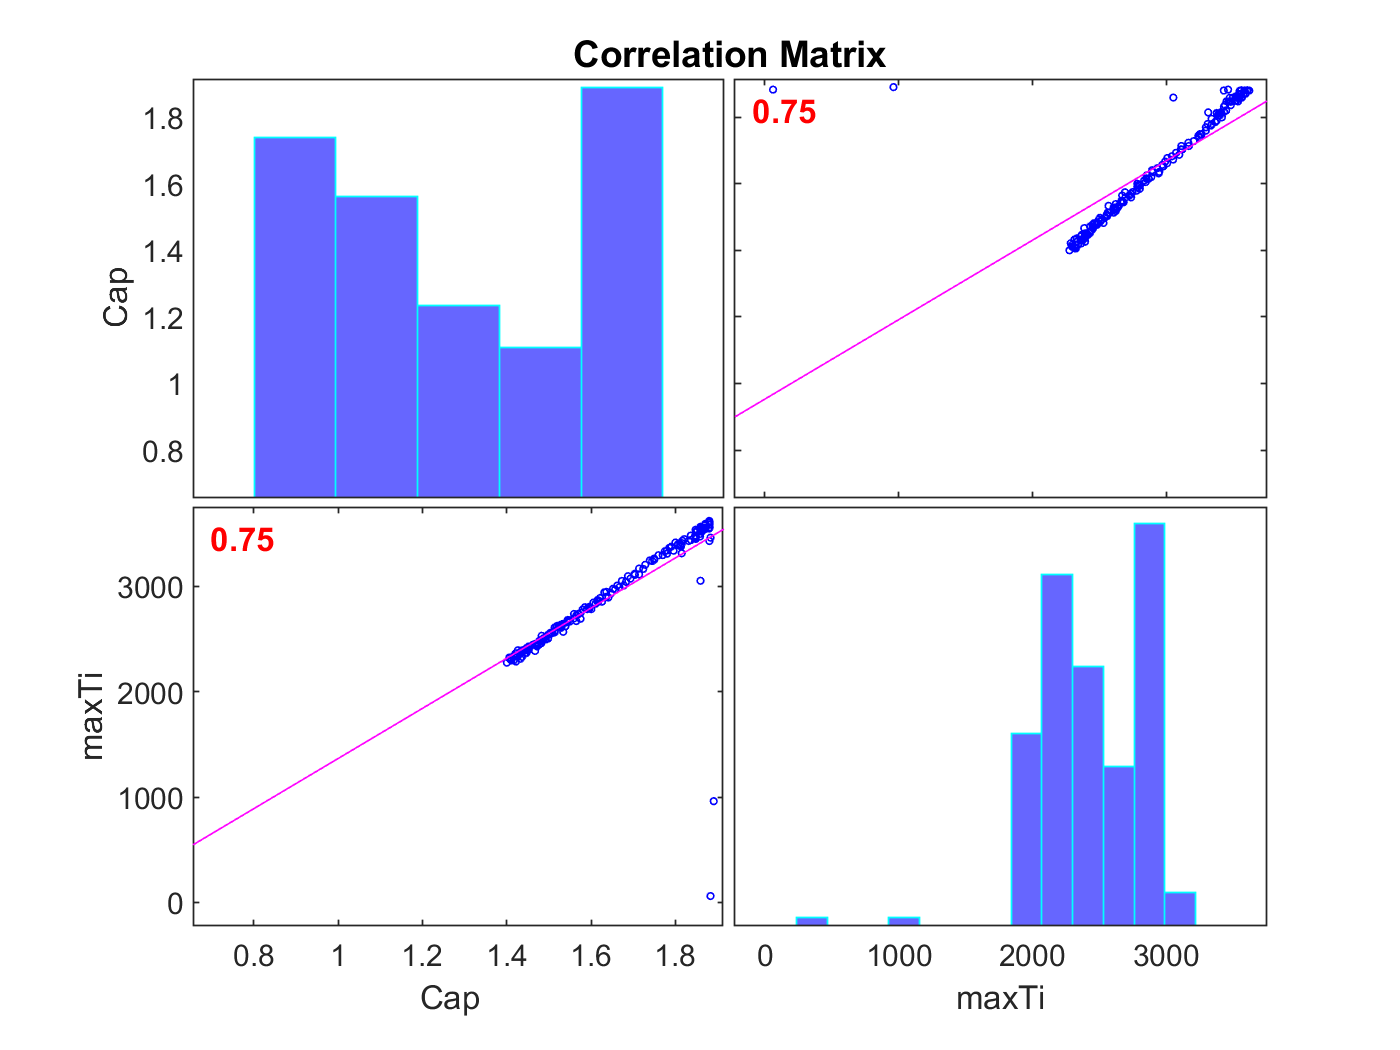

R =    1.000000000000000   0.753778988847614
   0.753778988847614   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector3,'type','Pearson','testR','on','varNames',{'Cap','maxTimeDelta'})

여기서 보면 outer 2개를 확인할 수 있다.

#### `Spearman`

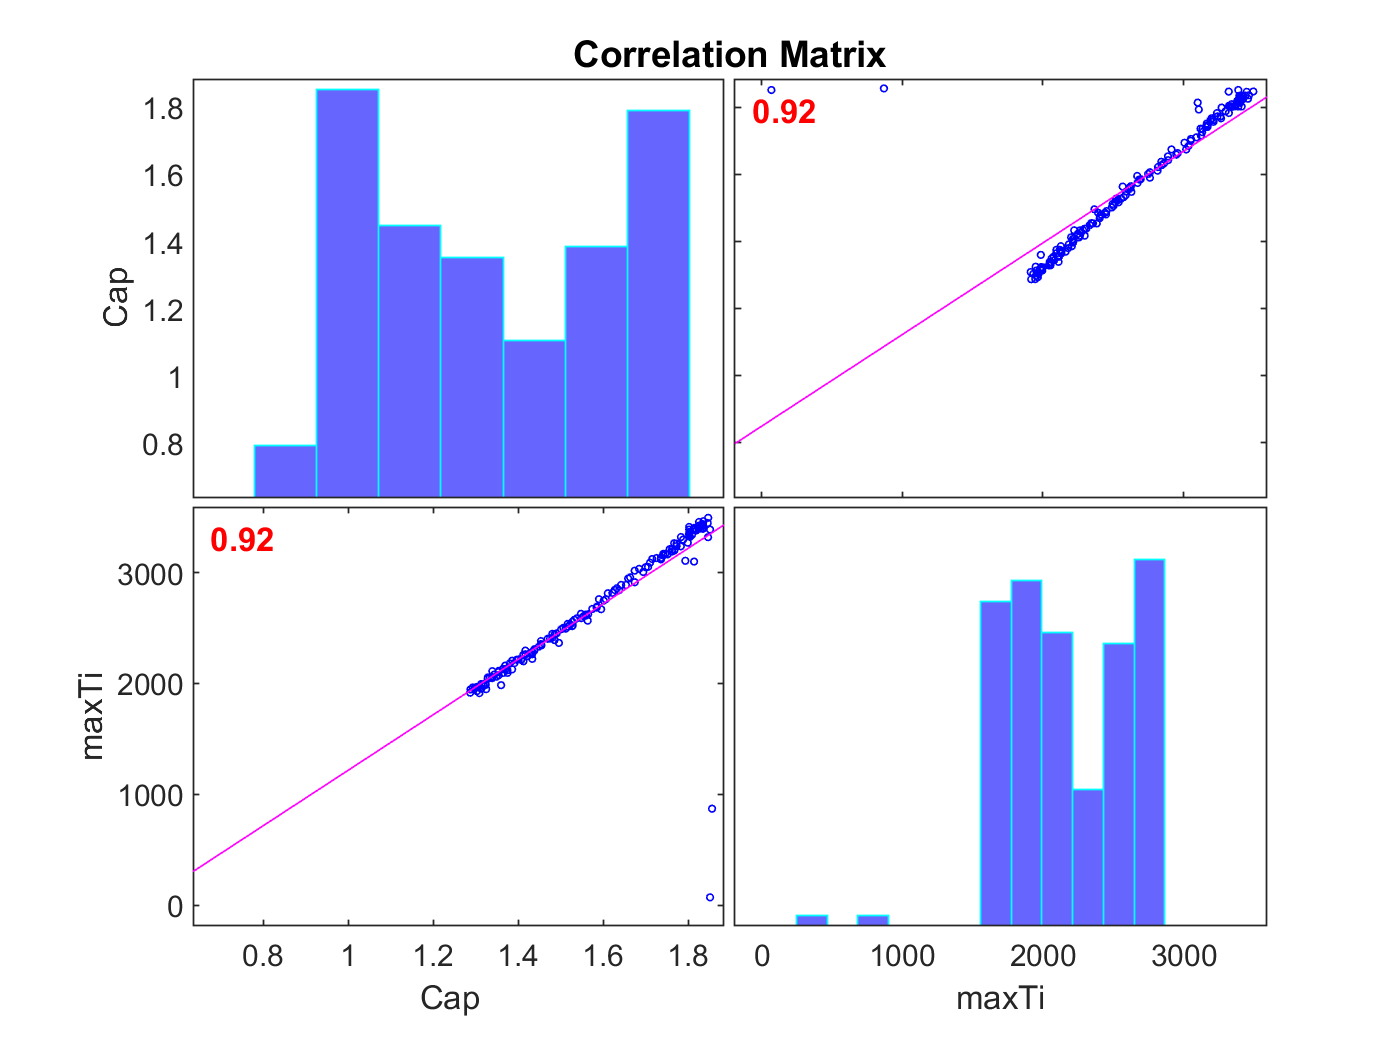

R =    1.000000000000000   0.922312319517792
   0.922312319517792   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector,'type','Spearman','testR','on','varNames',{'Cap','maxTimeDelta'})

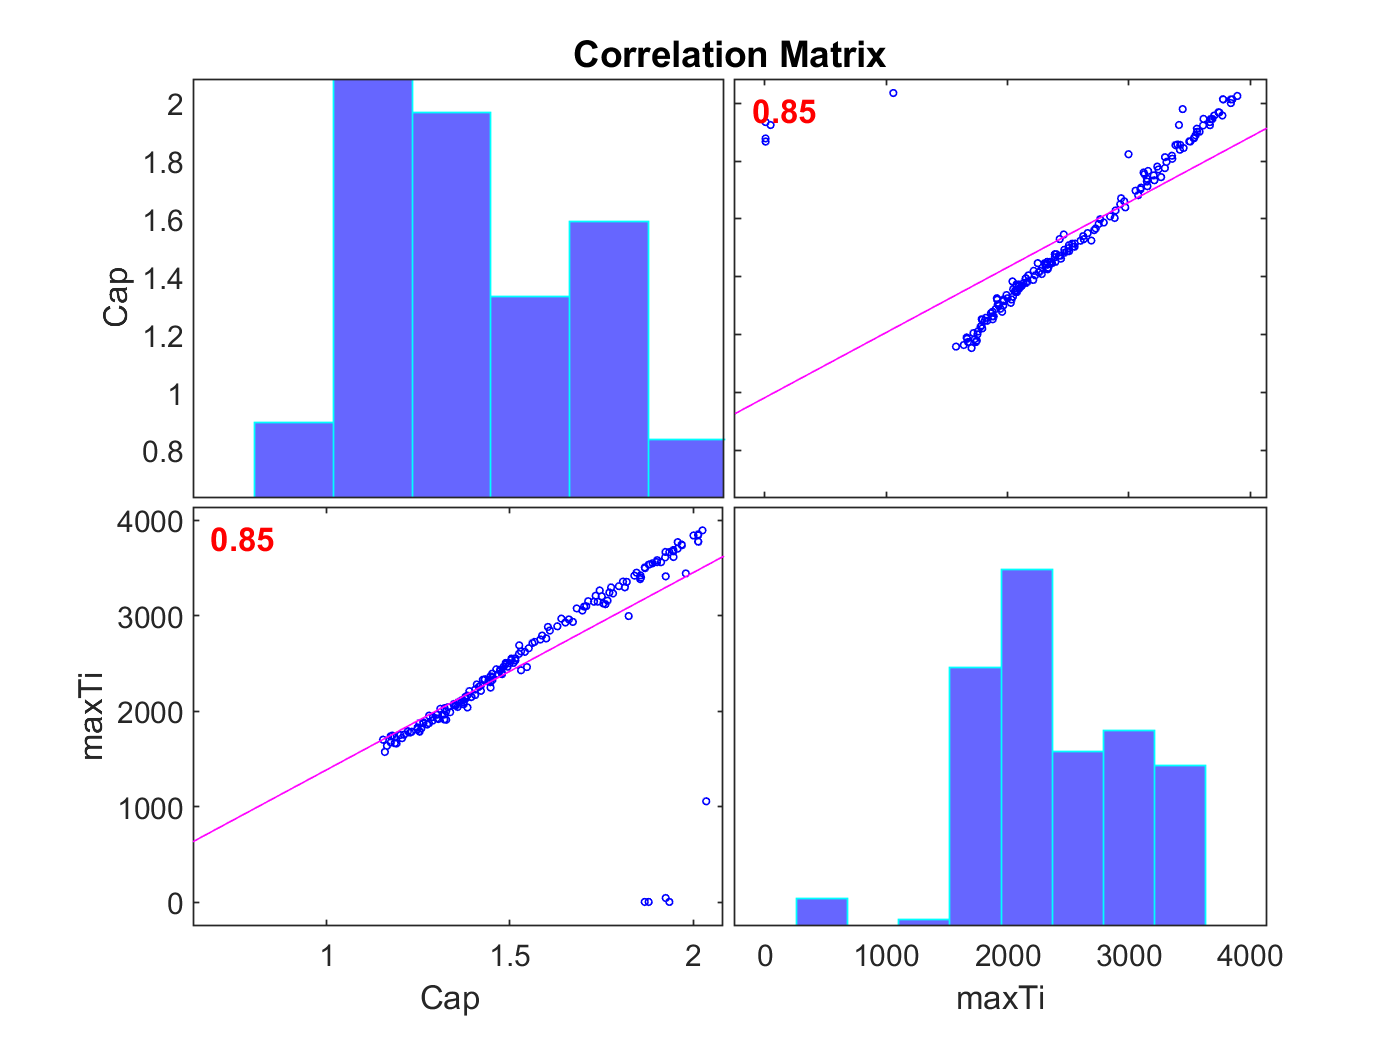

R =    1.000000000000000   0.854428987158170
   0.854428987158170   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector2,'type','Spearman','testR','on','varNames',{'Cap','maxTimeDelta'})

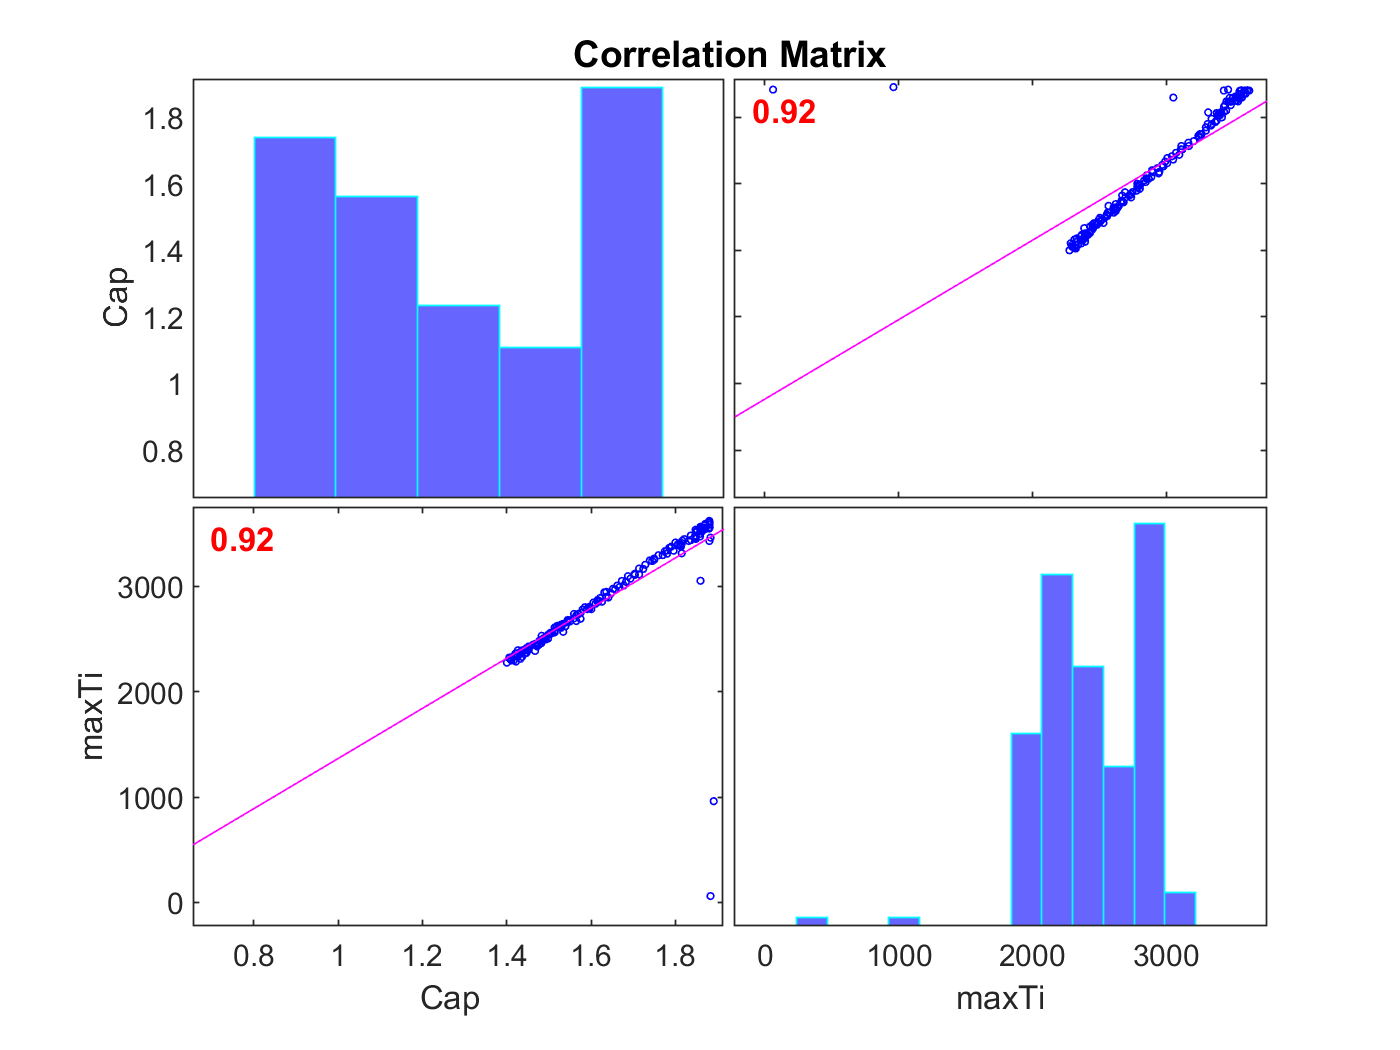

R =    1.000000000000000   0.921508032306456
   0.921508032306456   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector3,'type','Spearman','testR','on','varNames',{'Cap','maxTimeDelta'})

#### `Kendall`

R =    1.000000000000000   0.922312319517792
   0.922312319517792   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector,'type','Spearman','testR','on','varNames',{'Cap','maxTimeDelta'})

R =    1.000000000000000   0.854428987158170
   0.854428987158170   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector2,'type','Spearman','testR','on','varNames',{'Cap','maxTimeDelta'})

R =    1.000000000000000   0.921508032306456
   0.921508032306456   1.000000000000000


PValue =    1.000000000000000   0.000000000000000
   0.000000000000000   1.000000000000000


[R,PValue] = corrplot(dataVector3,'type','Spearman','testR','on','varNames',{'Cap','maxTimeDelta'})

#### 상관계수

**상관 분석**(相關 分析, Correlation analysis) 또는 '상관관계' 또는 '상관'은 [확률론](https://ko.wikipedia.org/wiki/%ED%99%95%EB%A5%A0%EB%A1%A0)과 [통계학](https://ko.wikipedia.org/wiki/%ED%86%B5%EA%B3%84%ED%95%99)에서 두 변수간에 어떤 선형적 또는 비선형적 관계를 갖고 있는지를 분석하는 방법이다.[[1]](https://ko.wikipedia.org/wiki/%EC%83%81%EA%B4%80_%EB%B6%84%EC%84%9D#cite_note-1) 두 변수는 서로 독립적인 관계이거나 상관된 관계일 수 있으며 이때 두 변수간의 관계의 강도를 상관관계(Correlation, Correlation coefficient)라 한다. 상관분석에서는 상관관계의 정도를 나타내는 단위로 모상관계수로 ρ를 사용하며 표본 상관 계수로 r 을 사용한다.

상관관계의 정도를 파악하는 [상관 계수](https://ko.wikipedia.org/wiki/%EC%83%81%EA%B4%80_%EA%B3%84%EC%88%98)(相關係數, Correlation coefficient)는 두 변수간의 연관된 정도를 나타낼 뿐 인과관계를 설명하는 것은 아니다. 두 변수간에 원인과 결과의 [인과관계](https://ko.wikipedia.org/wiki/%EC%9D%B8%EA%B3%BC%EA%B4%80%EA%B3%84)가 있는지에 대한 것은 [회귀분석](https://ko.wikipedia.org/wiki/%ED%9A%8C%EA%B7%80%EB%B6%84%EC%84%9D)을 통해 인과관계의 방향, 정도와 수학적 모델을 확인해 볼 수 있다.

## 기본 가정[[편집](https://ko.wikipedia.org/w/index.php?title=%EC%83%81%EA%B4%80_%EB%B6%84%EC%84%9D&action=edit&section=1)]

- [선형성](https://ko.wikipedia.org/wiki/%EC%84%A0%ED%98%95%EC%84%B1): 두 변인 X와 Y의 관계가 직선적인지를 알아보는 것으로 이 가정은 분포를 나타내는 [산점도](https://ko.wikipedia.org/wiki/%EC%82%B0%EC%A0%90%EB%8F%84)를 통하여 확인할 수 있다.

- [동변량성](https://ko.wikipedia.org/w/index.php?title=%EB%8F%99%EB%B3%80%EB%9F%89%EC%84%B1&action=edit&redlink=1): X의 값에 관계없이 Y의 흩어진 정도가 같은 것을 의미한다. [이분산성](https://ko.wikipedia.org/w/index.php?title=%EC%9D%B4%EB%B6%84%EC%82%B0%EC%84%B1&action=edit&redlink=1)이 반대어이다.

- 두 변인의 정규분포성: 두 변인의 측정치 분포가 [모집단](https://ko.wikipedia.org/wiki/%EB%AA%A8%EC%A7%91%EB%8B%A8)에서 모두 [정규분포](https://ko.wikipedia.org/wiki/%EC%A0%95%EA%B7%9C%EB%B6%84%ED%8F%AC)를 이루는 것이다.

- [무선독립표본](https://ko.wikipedia.org/w/index.php?title=%EB%AC%B4%EC%84%A0%EB%8F%85%EB%A6%BD%ED%91%9C%EB%B3%B8&action=edit&redlink=1): 모집단에서 [표본](https://ko.wikipedia.org/wiki/%ED%91%9C%EB%B3%B8)을 뽑을 때 표본대상이 [확률](https://ko.wikipedia.org/wiki/%ED%99%95%EB%A5%A0)적으로 선정된다는 것이다.[[2]](https://ko.wikipedia.org/wiki/%EC%83%81%EA%B4%80_%EB%B6%84%EC%84%9D#cite_note-2)

**피어슨 상관 계수**[[편집](https://ko.wikipedia.org/w/index.php?title=%EC%83%81%EA%B4%80_%EB%B6%84%EC%84%9D&action=edit&section=3)]

[피어슨 상관 계수](https://ko.wikipedia.org/wiki/%ED%94%BC%EC%96%B4%EC%8A%A8_%EC%83%81%EA%B4%80_%EA%B3%84%EC%88%98)(Pearson correlation coefficient 또는 Pearson's r)는 변수들간의 관련성을 구하는 [이변량 상관분석](https://ko.wikipedia.org/w/index.php?title=%EC%9D%B4%EB%B3%80%EB%9F%89_%EC%83%81%EA%B4%80%EB%B6%84%EC%84%9D&action=edit&redlink=1)(bivariate analysis 또는 bivariate correlation analysis)에서 보편적으로 이용된다. 개념은 다음과 같다.

{\displaystyle r={{\text{X 와 Y 가 함 께 변 하 는 정 도 }} \over {\text{X 와 Y 가 각 각 변 하 는 정 도 }}}}

- 결과의 해석

r 값은 X 와 Y 가 완전히 동일하면 +1, 전혀 다르면 0, 반대방향으로 완전히 동일 하면 –1 을 가진다. [결정계수](https://ko.wikipedia.org/wiki/%EA%B2%B0%EC%A0%95%EA%B3%84%EC%88%98)(coefficient of determination)는 {\displaystyle r^{2}} 로 계산하며 이것은 X 로부터 Y 를 예측할 수 있는 정도를 의미한다.

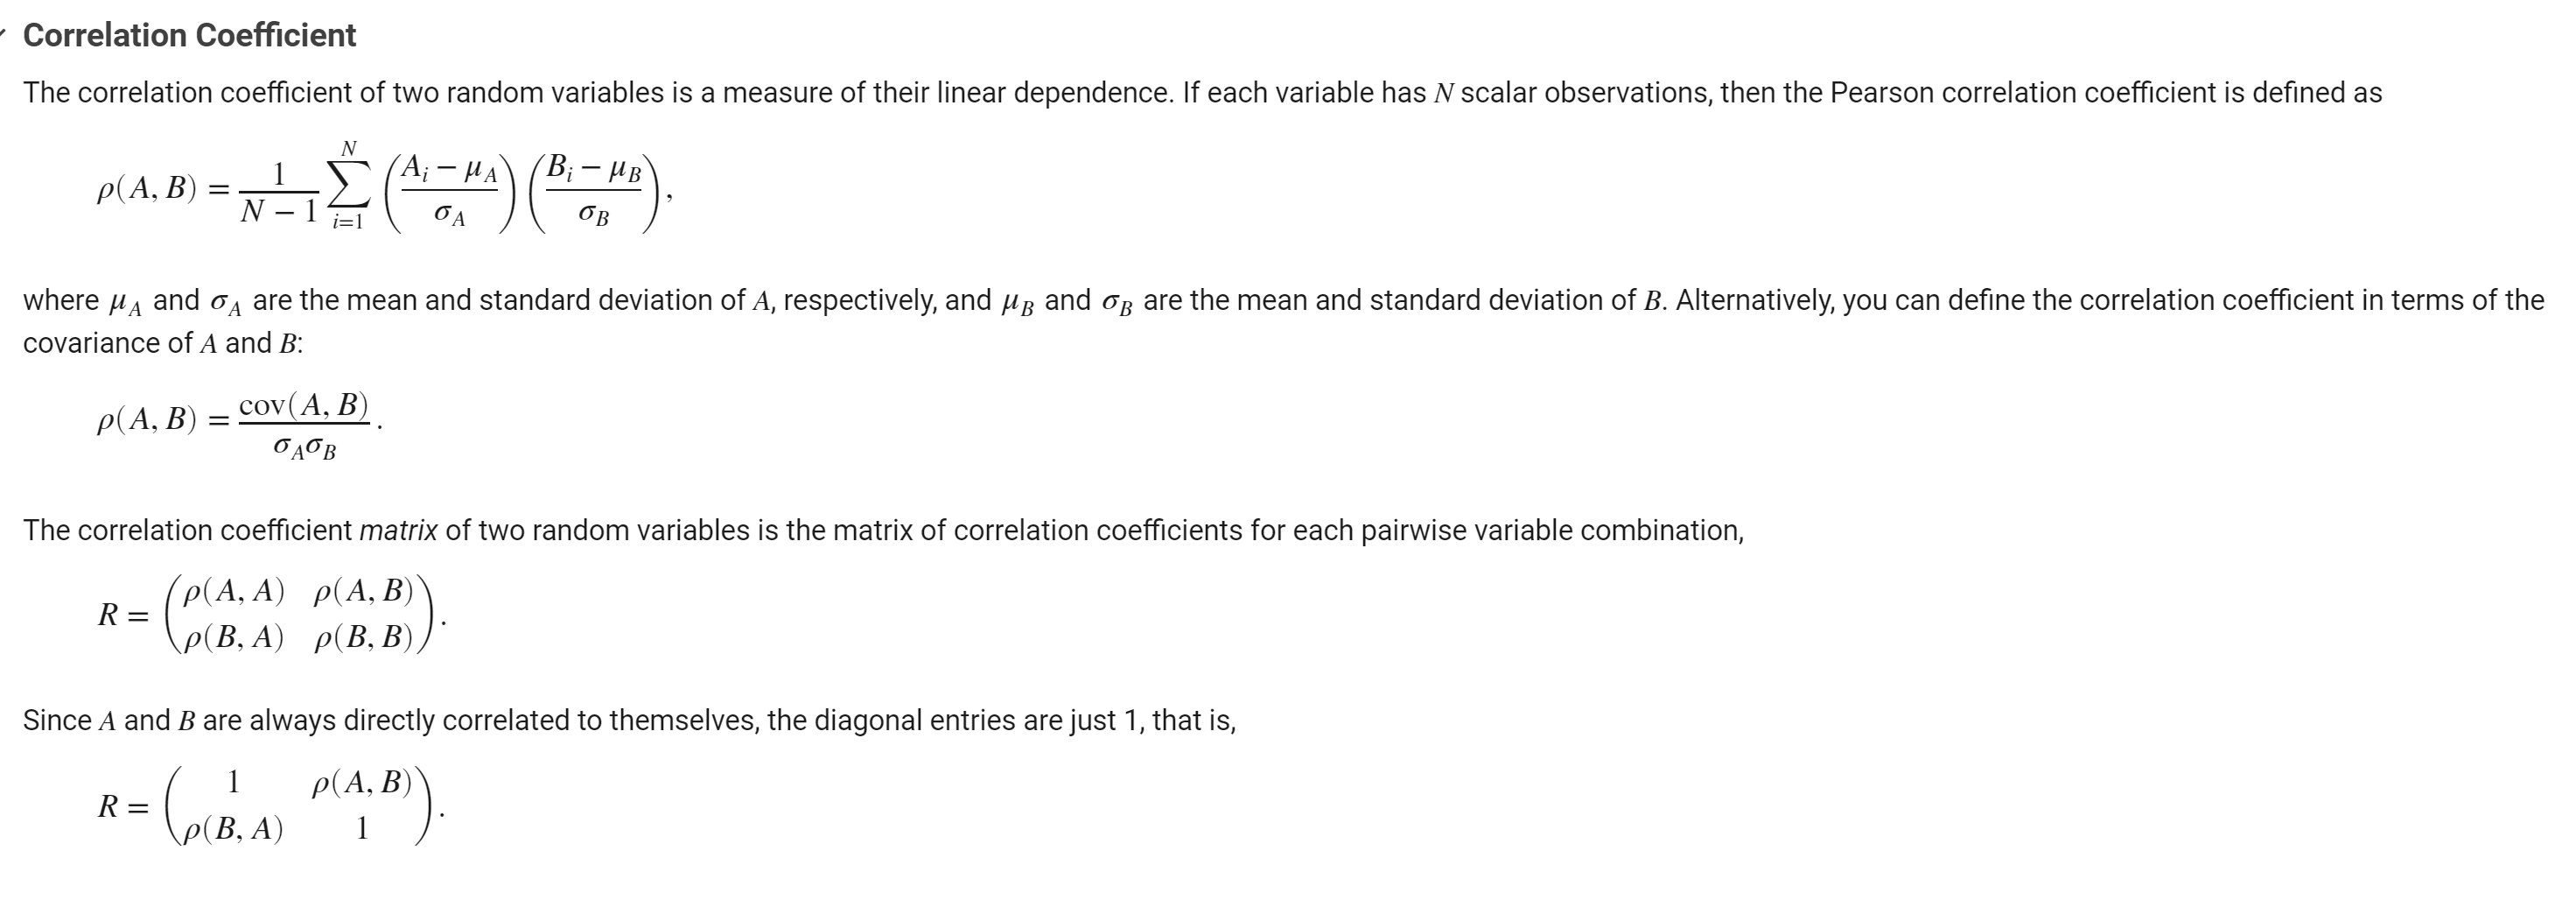

상관계수는 이미 정규화가 된 상태에서의 값이다. 평균과 표준편차가 수식에 있으므로.

P-values, returned as a matrix. `P` is symmetric and is the same size as `R`. The diagonal entries are all ones and the off-diagonal entries are the p-values for each variable pair. P-values range from 0 to 1, where values **close to 0 correspond to a significant correlation in **`R`** and a low probability of observing the null hypothesis.**

P 밸류가 0에 가까우면 R의 유의한 상관관계가 있도 이는 귀무가설이 낮은 확율을 가져서 귀무가설을 기각한다.

#### 공분산

공분산은 2개의 확률변수의 선형 관계를 나타내는 값이다. 만약 2개의 변수중 하나의 값이 상승하는 경향을 보일 때 다른 값도 상승하는 선형 상관성이 있다면 양수의 공분산을 가진다

공분산은 정규화가 되어 있지않으므로 정규화를 해야 한다.

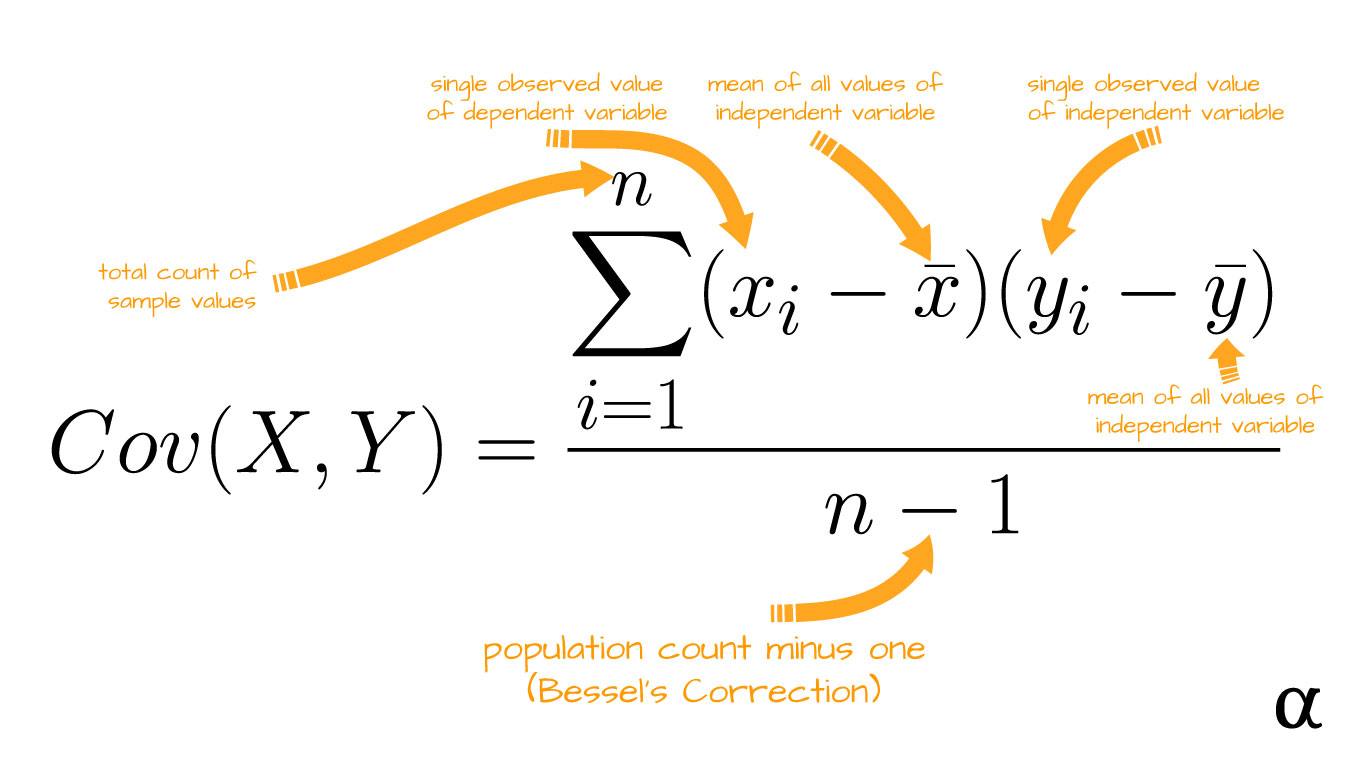


x = randn(6,1)

x =    0.725404224946106
  -0.063054873189656
   0.714742903826096
  -0.204966058299775
  -0.124144348216312
   1.489697607785465


y = randn(6,1)

y =    1.409034489800479
   1.417192413429614
   0.671497133608080
  -1.207486922685038
   0.717238651328838
   1.630235289164729


A = [x y 2*y+3  2*x+3]

A =    0.725404224946106   1.409034489800479   5.818068979600959   4.450808449892211
  -0.063054873189656   1.417192413429614   5.834384826859228   2.873890253620687
   0.714742903826096   0.671497133608080   4.342994267216161   4.429485807652192
  -0.204966058299775  -1.207486922685038   0.585026154629924   2.590067883400451
  -0.124144348216312   0.717238651328838   4.434477302657677   2.751711303567376
   1.489697607785465   1.630235289164729   6.260470578329459   5.979395215570930


R = corrcoef(A)

R =    1.000000000000000   0.580646917598479   0.580646917598479   1.000000000000000
   0.580646917598479   1.000000000000000   1.000000000000000   0.580646917598479
   0.580646917598479   1.000000000000000   1.000000000000000   0.580646917598479
   1.000000000000000   0.580646917598479   0.580646917598479   1.000000000000000


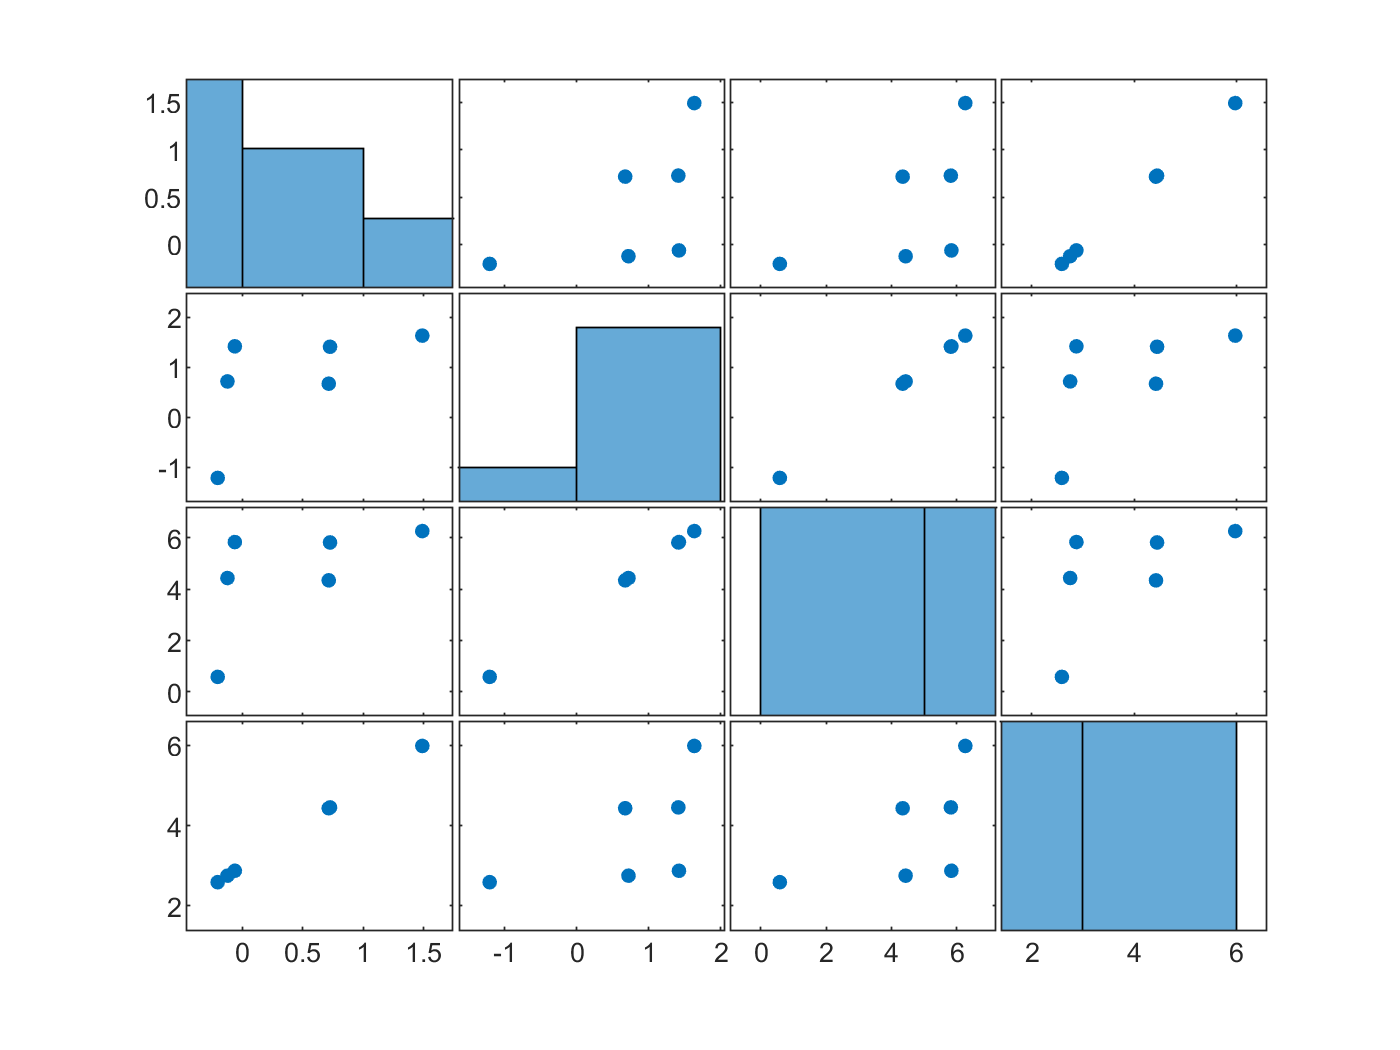

figure
plotmatrix(A)

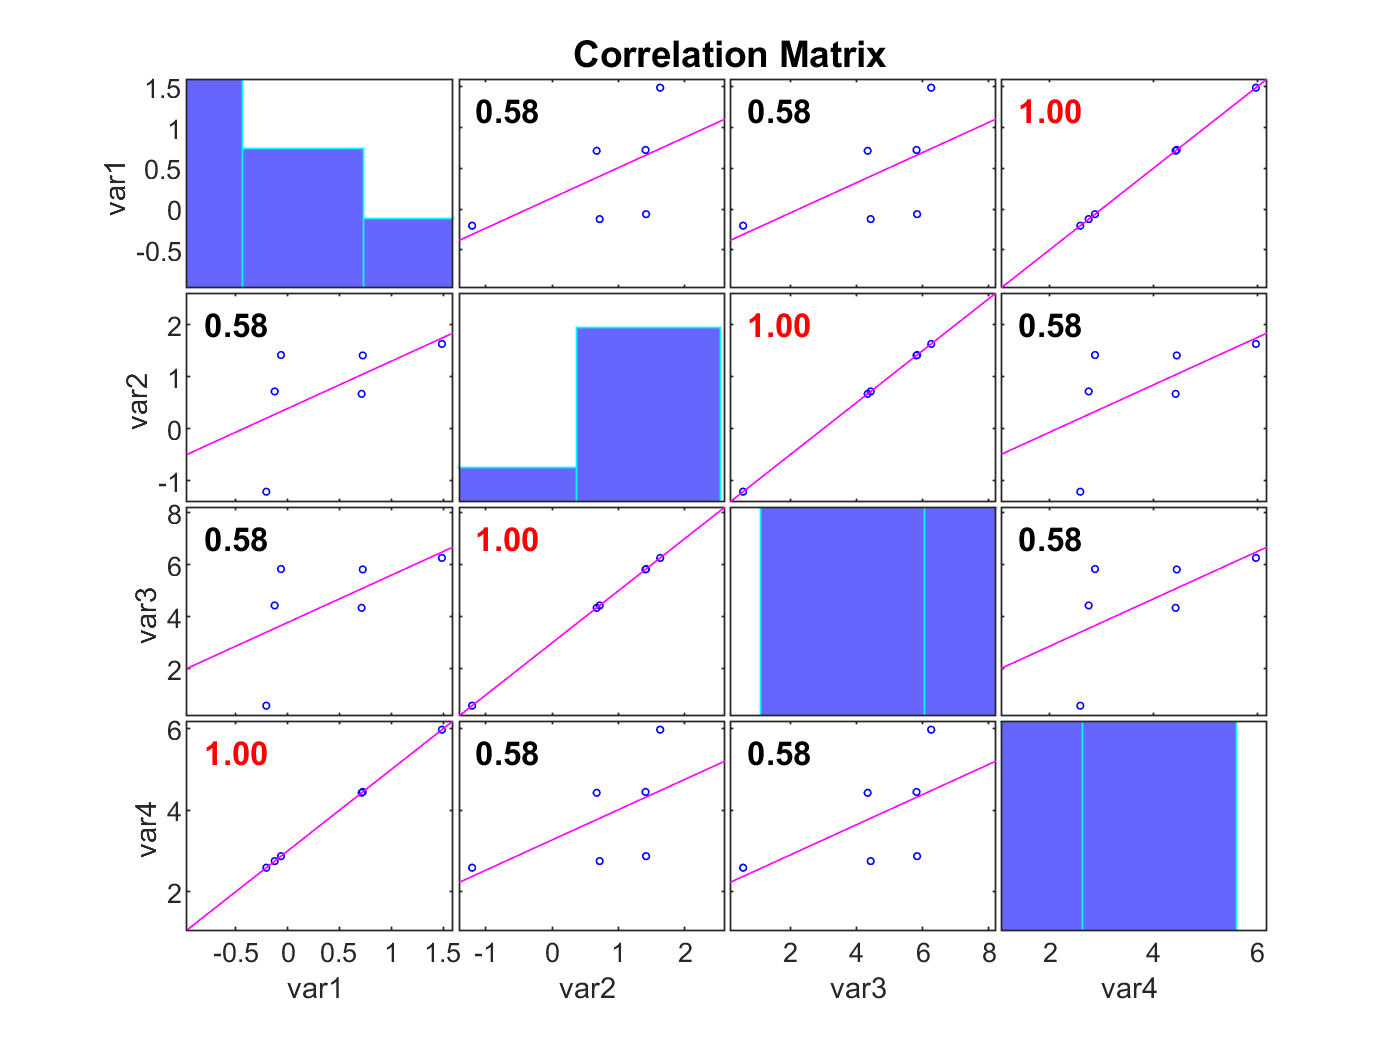


figure
corrplot(A,'type','Pearson','testR','on')

[](https://ko.wikipedia.org/wiki/%EC%83%81%EA%B4%80_%EB%B6%84%EC%84%9D)